clear
close all
clc

Et reguleringssystem har G_P:

G_P = tf([3],[0.5 1.5 1])


G_P =
 
           3
  -------------------
  0.5 s^2 + 1.5 s + 1
 
Continuous-time transfer function.



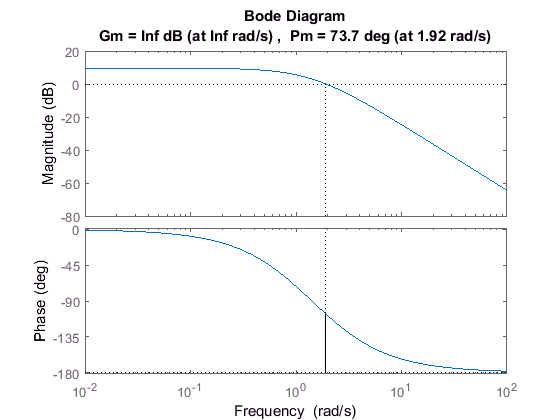

margin(G_P)

Delopgave 1)

Bestem en LAG-kompensator, så systemet får en åben sløjfe DC-forstærkning på 40 dB og en fasemargen på 55 grader.

Der vælges en krydsfrekvens på 4 gange polfrekvensen, derfor er fasen -14 grader for kompensatoren. Herefter findes den påkrævede fase for den åbne sløjfe.

syms G_O_P
55 == 180 + G_O_P - 14;
G_O_P = solve(ans,G_O_P)

$$G\_O\_P = -111$$

Krydsfrekvensen aflæses på bodeplottet. Ved -111 grader, er frekvensen 2,1 rad/s.

Denne anvendes til at finde tau_i. Der anvendes 4/w_c, da krydsfrekvensen er 4 gange polfrekvensen.

w_c = 2.1

w_c = 2.1000

tau_i = 4/w_c

tau_i = 1.9048

DC-forstærkningen skal indstilles til 40 dB.

DC-forstærkningen fra G_P er lig 3.

10^(40db/20) = G_P * K_p

K_p=(10^(40/20))/3

K_p = 33.3333

Der aflæses på bodeplottet, at ved den ønskede krydsfrekvens er amplituden -1,1. Dette skal justeres med beta-værdien, så amplituden er 0.

K_p/Beta = 10^(1.1/20)

Beta=K_p/(10^(1.1/20))

Beta = 29.3683

Derfor er den samlede overføringsfunktion for regulatoren

G_C = K_p*tf([tau_i 1],[Beta*tau_i 1])


G_C =
 
  63.49 s + 33.33
  ---------------
    55.94 s + 1
 
Continuous-time transfer function.



Delopgave 2)

Bestem størrelsen af den stationære fejl ess, når inputtet er step med højden 1.

G_L = feedback(G_C*G_P,1)


G_L =
 
              190.5 s + 100
  -------------------------------------
  27.97 s^3 + 84.41 s^2 + 247.9 s + 101
 
Continuous-time transfer function.



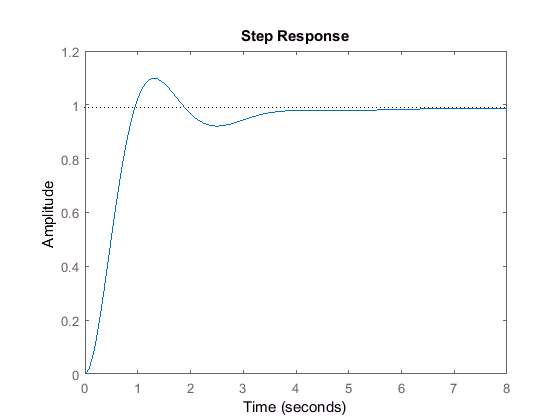

H0 = 1;
step(G_L*H0)

Ved hjælp af tabel 3.1:

K0 = 3*K_p; %3 er DC-forstærkningen af G_P, mens K_p er DC-forstærkning af G_C
ess = H0/(1+K0)

ess = 0.0099